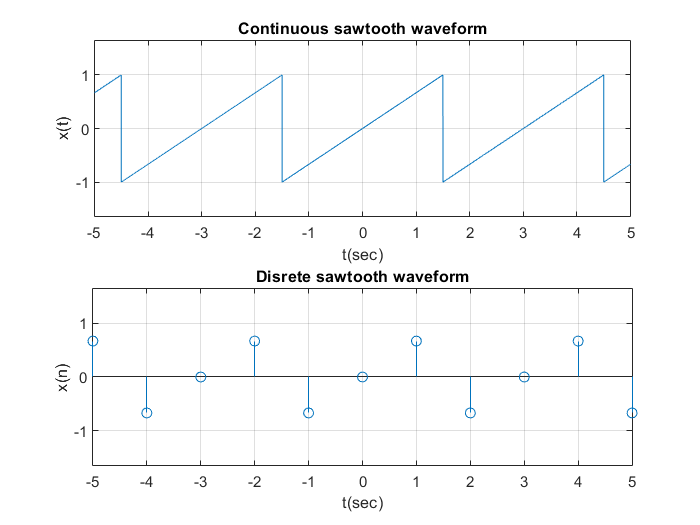

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

t=-5:0.001:5; 
fp=3;
x = 2*t/fp - 2*ceil(t/fp-0.5); %Continuous sawtooth waveform
figure;
subplot(2,1,1);
plot(t,x);
title('Continuous sawtooth waveform');
xlabel('t(sec)');
ylabel('x(t)');
grid on;
axis equal;

t1=-5:5; 
x1 = 2*t1/fp - 2*ceil(t1/fp-0.5);   %Disrete sawtooth waveform
subplot(2,1,2);
stem(t1,x1);
title('Disrete sawtooth waveform');
xlabel('t(sec)');
ylabel('x(n)');
grid on;
axis equal;

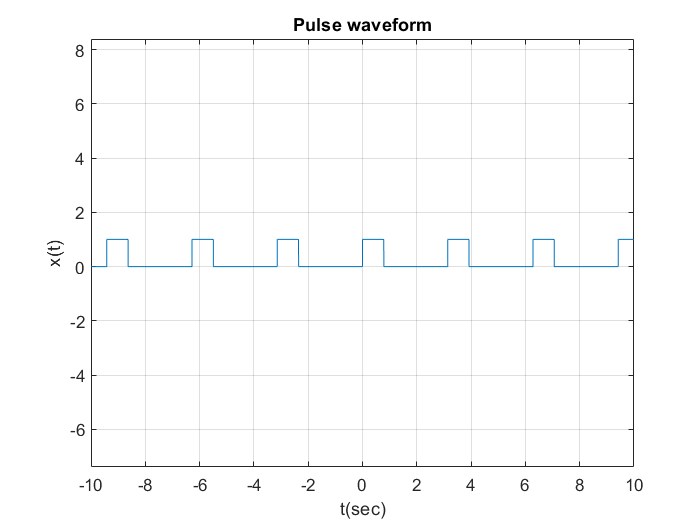

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

%Pulse waveform

t=-10:0.001:10;
t1=mod(t,pi);
x=zeros(1,length(t));
x(t1<=pi/4)=1;
x(and(t1>pi/4,t1<=pi))=0;
figure;
plot(t,x);
xlabel('t(sec)');
ylabel('x(t)');
title('Pulse waveform');
grid on;
axis equal;

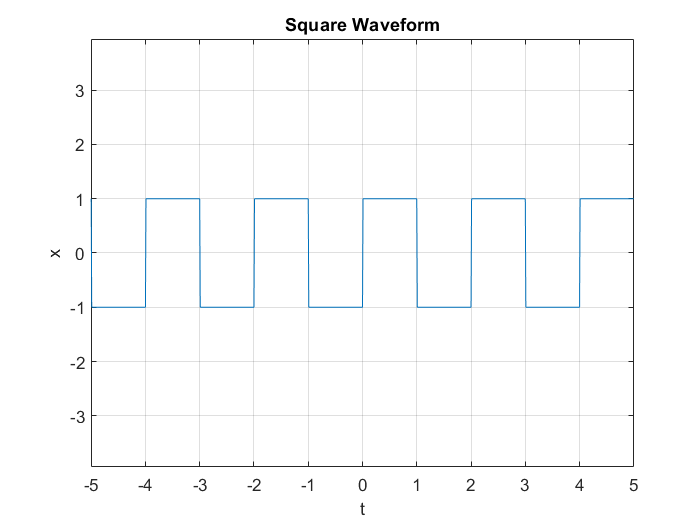

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

%Square Waveform

t=-5:0.01:5;
for i=1:length(t)
    if mod(ceil(t(i)), 2)==0
        x(i) = -1;
    else
        x(i) = 1;
    end
end
figure;

plot(t,x);
title('Square Waveform');
xlabel('t');
ylabel('x');
grid on;
axis equal;

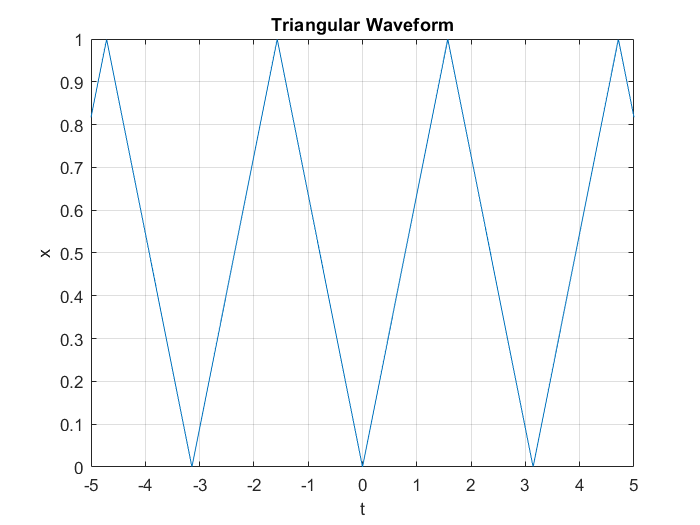

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

%Triangular waveform

t=-5:0.01:5;
fp=pi;  %fp is fundamental period
t1=mod(t,fp);
x=zeros(1,length(t));
x(t1<=fp/2)=2*t1(t1<=fp/2)/fp;
x(and(t1>fp/2,t1<=fp))=2*(1-t1(and(t1>fp/2,t1<=fp))/fp);

figure;
plot(t,x);
title('Triangular Waveform');
xlabel('t');ylabel('x');
grid on; 

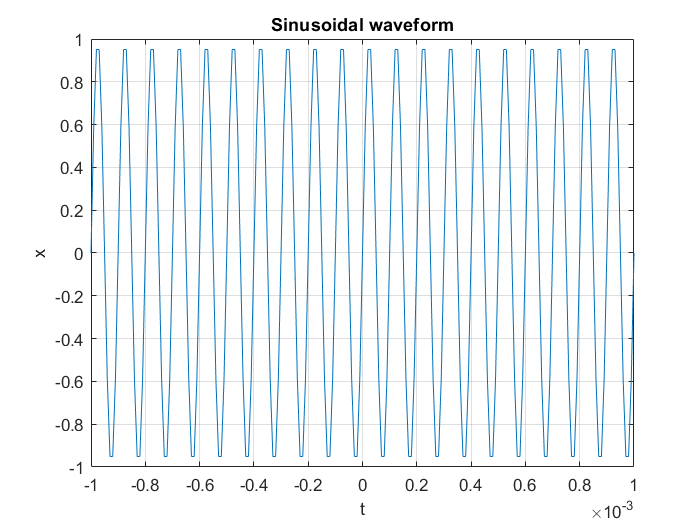

clc; %clears screen
clear all;  %clears all variables
close all;  %closes all created windows

%----------------------------------

%Sinusoidal waveform with frequency 1ms

t=-0.001:0.00001:0.001;
fp=0.0001;
x=sin(2*pi*t/fp);

figure;
plot(t,x);grid on;
title('Sinusoidal waveform');
xlabel('t');
ylabel('x');
axis fill;